# **Classificació d'objectes**

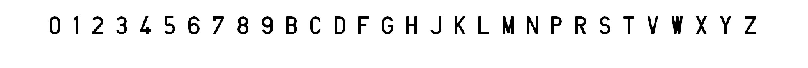

I = rgb2gray(imread('Joc_de_caracters.jpg'));
imshow(I)

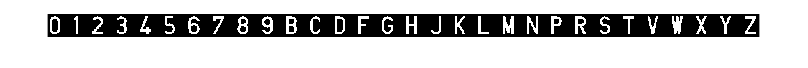

BW = I<126;
imshow(BW)

CC = bwconncomp(BW)

CC = struct with fields:
    Connectivity: 8
       ImageSize: [72 2228]
      NumObjects: 30
    PixelIdxList: {1×30 cell}


props = regionprops('table',BW,'Area','Perimeter','BoundingBox')

props = 30×3 table
    Area                BoundingBox                 Perimeter
    ____    ____________________________________    _________

     978       6.5       7.5        34        57     147.18  
     523      82.5       7.5        15        57     135.98  
     816     140.5       7.5        34        57      226.7  
     796     216.5       7.5        33        57     225.21  
     722     291.5       7.5        33        57     188.95  
     797     367.5       7.5        32        57     231.17  
    1053     441.5       7.5        35        57     203.88  
     729     518.5       7.5        34        57     200.19  
    1026     595.5       7.5        33        57     153.21  
    1021     671.5       7.5        34        57     198.55  
    1176     747.5       7.5        34        57     164.34  
     725     823.5       7.5        32        57     212.52  
    1045  

C1 = props.Area;
C2 = props.Perimeter;
C3 = props.BoundingBox(:,3);
C4 = props.BoundingBox(:,4);

X = [C1 C2 C3 C4];
Y =  ['0'; '1'; '2'; '3'; '4'; '5'; '6'; '7'; '8'; '9'; 'B'; 'C'; 'D'; 'F'; 'G'; 'H'; 'J'; 'K'; 'L'; 'M'; 'N'; 'P'; 'R'; 'S'; 'T'; 'V'; 'W'; 'X'; 'Y'; 'Z'];
Mdl = TreeBagger(100,X,Y)

Mdl =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:               [30x4]
                    Training Y:               [30x1]
                        Method:       classification
                 NumPredictors:                    4
         NumPredictorsToSample:                    2
                   MinLeafSize:                    1
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    0
 ComputeOOBPredictorImportance:                    0
                     Proximity:                   []
                    ClassNames:             '0'             '1'             '2'             '3'             '4'             '5'             '6'             '7'             '8'             '9'             'B'             'C'             'D'             'F'             'G'             'H'             'J'           

[Ypredicted, certainty] = predict(Mdl,X);
PL = cell2mat(Ypredicted);
TL = cell2mat(num2cell(Y));
sum(PL == TL)

ans = 30

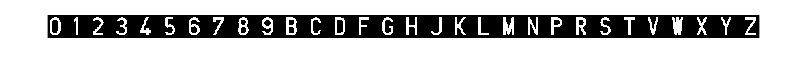

%%probem amb una imatge diferent (mes gran)
Ig = imresize(I,15);
BW = Ig<126;
imshow(BW);

CC = bwconncomp(BW);
props = regionprops('table',BW,'Area','Perimeter','BoundingBox');
C1 = props.Area;
C2 = props.Perimeter;
C3 = props.BoundingBox(:,3);
C4 = props.BoundingBox(:,4);

X = [C1 C2 C3 C4];
Y =  ['0'; '1'; '2'; '3'; '4'; '5'; '6'; '7'; '8'; '9'; 'B'; 'C'; 'D'; 'F'; 'G'; 'H'; 'J'; 'K'; 'L'; 'M'; 'N'; 'P'; 'R'; 'S'; 'T'; 'V'; 'W'; 'X'; 'Y'; 'Z'];
[Ypredicted, certainty] = predict(Mdl,X);
PL = cell2mat(Ypredicted);
TL = cell2mat(num2cell(Y));
%% no va
sum(PL == TL)

ans = 1

%%probem a fer l'area i el perimetre proporcionals
C1 = props.Area./(props.Perimeter.*props.Perimeter);
C2 = props.Perimeter./(props.BoundingBox(:,3)); %W
C3 = props.Perimeter./(props.BoundingBox(:,4)); %H
C4 = props.BoundingBox(:,3)./props.BoundingBox(:,4); %W/H
X = [C1 C2 C3 C4];
Y =  ['0'; '1'; '2'; '3'; '4'; '5'; '6'; '7'; '8'; '9'; 'B'; 'C'; 'D'; 'F'; 'G'; 'H'; 'J'; 'K'; 'L'; 'M'; 'N'; 'P'; 'R'; 'S'; 'T'; 'V'; 'W'; 'X'; 'Y'; 'Z'];
Mdl = TreeBagger(100,X,Y);
[Ypredicted, certainty] = predict(Mdl,X);
PL = cell2mat(Ypredicted);
TL = cell2mat(num2cell(Y));
%% si va :)
sum(PL == TL)

ans = 30

Y = 1:30

Y =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


X = 1:30

X =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30
